label = csvread ('label1.csv')

label =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


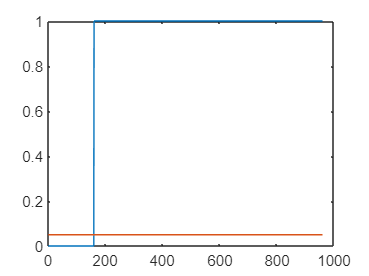

plot(label)
hold on
x = 1:960;
y(x) = 0.05;

plot(y)
output = score > 0.05;
hold off

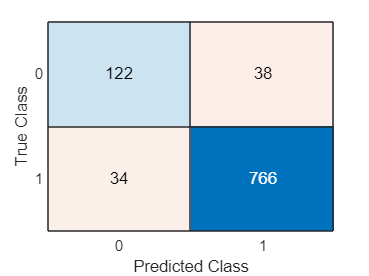

confusionchart(label,double(output))

tp = 766,fp = 38, fn=34, tn = 122

tp = 766

fp = 38

fn = 34

tn = 122

precision

Precision = tp\(tp+fp)

Precision = 1.0496

recall

Recall = tp/(tp+fn)

Recall = 0.9575

accuracy

Accuracy = (tp+tn)/960

Accuracy = 0.9250

f1_score

f1_score = 2*tp/(2*tp+fp+fn)

f1_score = 0.9551

roc

[tpr, fpr, thresholds] = roc(label, score);

'roc' requires Deep Learning Toolbox.

plot(fpr,tpr)

auc

AUC = trapz(fpr,tpr)